# Test Road Detection Try 1

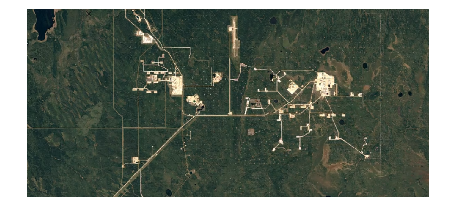

clf
im1 = imread('../images/canada_mining_road.png');
imshow(im1)

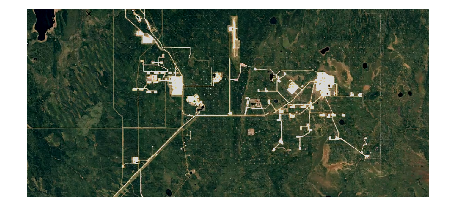


% higher contrast
im1 = im1 * 1.5 - 40;
imshow(im1)

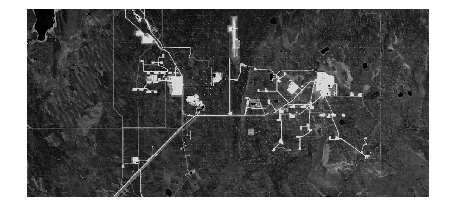


% just grayscale
im1_gray = rgb2gray(im1);
imshow(im1_gray)


% enhance contrast
im1 = imadjust(im1_gray)

im1 = 632×1352 uint8 矩阵
    34    35    31    25    18    13     4     0     5    18    23    21    16    11    11    23    44    39    84   134   139   107    50    11     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    30    29    30    25    21    20     5     0     4    14    19    21    21    18    15    18    25    30    78   127   134   114    54    10     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    33    29    31    31    30    29    10     5    13    26    29    23    18    16    18    21    20    10    64   128   141   132    64     5     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    36    34    35    38    40    39    24    14    16    24    26    21 

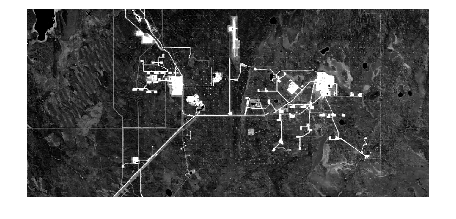

imshow(im1)

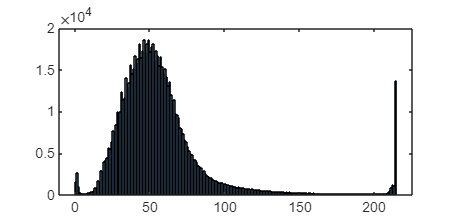

% binarize
histogram(im1_gray)

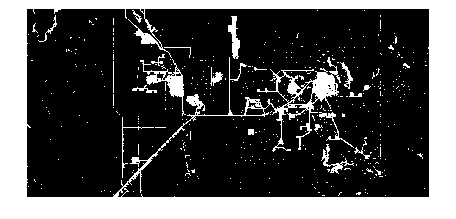

BW = imbinarize(im1_gray,100/256);
imshow(BW)

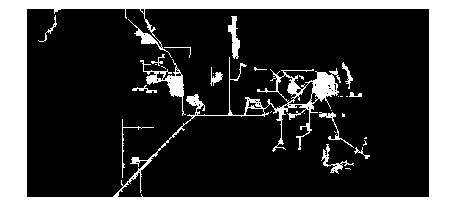


% remove noise
BW2 = bwareafilt(BW,4);
imshow(BW2)

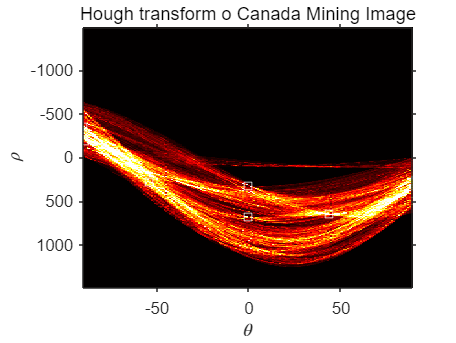


% hough line detection
bw1 = edge(BW2,'canny');
[H,T,R] = hough(bw1);

% plot hough graph
figure;
imshow(imadjust(rescale(H)),'XData',T,'YData',R,...
      'InitialMagnification','fit');
title('Hough transform o Canada Mining Image');
xlabel('\theta'), ylabel('\rho');
axis on, axis normal, hold on;
colormap(gca,hot);

P  = houghpeaks(H,20);
%P = houghpeaks(H, 10, 'Threshold', 0.3 * max(H(:)));
x = T(P(:,2)); y = R(P(:,1));
plot(x,y,'s','color','white');

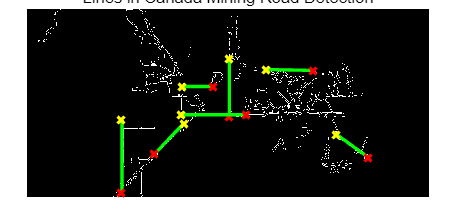


figure;
lines = houghlines(bw1,T,R,P,'FillGap', 25, 'MinLength',100);
imshow(bw1), hold on
max_len = 0;
for k = 1:length(lines)
   xy = [lines(k).point1; lines(k).point2];
   plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');

   % Plot beginnings and ends of lines
   plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
   plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');

   % Determine the endpoints of the longest line segment
   len = norm(lines(k).point1 - lines(k).point2);
   if ( len > max_len)
      max_len = len;
      xy_long = xy;
   end
end
title('Lines in Canada Mining Road Detection')